Interface de texto para PVI

Autor:

  - Arménio Correia  .: armenioc@isec.pt

  - Ana Rita Conceição Pessoa - 2023112690 

  - João Francisco de Matos Claro - 2023112690 

Data : 13/03/2024

clear
numPlot = 1; %flag to draw the plot dynamically
metodos(1) = "";
% syms y(t)

strF="y+exp(3*t)";
%f=@(t,y) eval(vectorize(strF));
f=str2func(vectorize(strcat('@(t,y)', " ", strF)));
a = 0;
b = 1.5;
if ~(isscalar(b) && b > a)
    disp("Introduza um b > a");
end
n = 3;
if ~(isscalar(n) && n==floor(n) && n > 0)
    disp("Introduza um valor de n correto");
end
y0 = 2;

%Alinha automaticamente os graficos consoante o numero
tiledlayout('flow');

if(true)
    [t, y]=NEuler(f,a,b,n,y0);

    mostraAproximacoes("Euler", y);
    mostraGrafico("Euler", y, t);

    metodos(numPlot) = "Euler";
    numPlot = numPlot + 1;
end


Aproximações obtidas Euler:
                   y               
    _______________________________

    2       3.5    7.4908    21.279



if(false)
    [t, y]=NEulerMelhorado(f,a,b,n,y0);

    mostraAproximacoes("Euler Melhorado", y);
    mostraGrafico("Euler Melhorado", y, t);

    metodos(numPlot) = "Euler Melhorado";
    numPlot = numPlot + 1;
end
if(true)
    [t, y]=RK2(f,a,b,n,y0);

    mostraAproximacoes("RK2", y);
    mostraGrafico("RK2", y, t);

    metodos(numPlot) = "RK2";
    numPlot = numPlot + 1;
end


Aproximações obtidas RK2:
                   y               
    _______________________________

    2    4.7454    14.413    53.458



if(true)
    [t, y]=RK4(f,a,b,n,y0);

    mostraAproximacoes("RK4", y);
    mostraGrafico("RK4", y, t);

    metodos(numPlot) = "RK4";
    numPlot = numPlot + 1;
end


Aproximações obtidas RK4:
                   y               
    _______________________________

    2    4.4043    12.348     43.36



if(true)
    [tode, yode]=ode45(f, [a b], y0);

    %nao pode ser usada na funcao mostraGrafico
    %porque usa um t diferente das outras funcoes
    mostraAproximacoes("ode45", yode);
    mostraGrafico("ode45", yode, tode);
    fprintf('\nPontos de aproximação da ode45\n');
    disp(table(tode));
end


Aproximações obtidas ode45:
      y   
    ______

         2
    2.1039
    2.2152
    2.3344
    2.4624
    2.6169
    2.7845
    2.9666
    3.1646
    3.3803
    3.6156
    3.8724
    4.1532
    4.4605
    4.7973
    5.1668
    5.5725
    6.0185
    6.5094
      7.05
    7.6461
    8.3038
    9.0303
    9.8331
    10.721
    11.704
    12.793
        14
    15.338
    16.824
    18.473
    20.305
    22.341
    24.605
    27.123
    29.925
    33.045
     36.52
     40.39
    44.703
    49.511
    50.056
    50.608
    51.166
    51.731




Pontos de aproximação da ode45


      tode  
    ________

           0
    0.033492
    0.066984
     0.10048
     0.13397
     0.17147
     0.20897
     0.24647
     0.28397
     0.32147
     0.35897
     0.39647
     0.43397
     0.47147
     0.50897
     0.54647
     0.58397
     0.62147
     0.65897
     0.69647
     0.73397
     0.77147
     0.80897
     0.84647
     0.88397
     0.92147
     0.95897
     0.99647
       1.034
      1.0715
       1.109
      1.1465
       1.184
      1.2215
       1.259
      1.2965
       1.334
      1.3715
       1.409
      1.4465
       1.484
       1.488
       1.492
       1.496
         1.5



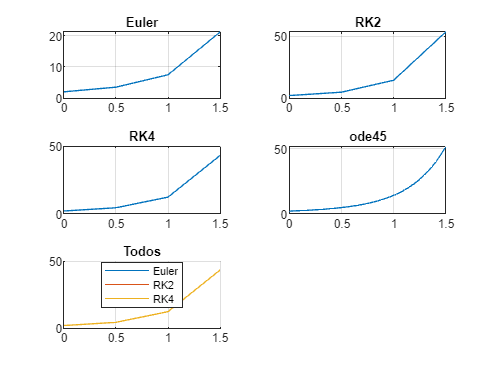

if(false)
    [t, y]=AdamBashford(f,a,b,n,y0);

    mostraAproximacoes("Adams-Bashforth", y);
    mostraGrafico("Adams-Bashforth", y, t);

    metodos(numPlot) = "Adams-Bashforth";
    numPlot = numPlot + 1;
end
if(false)
    [t, y]=sExata(f,a,b,n,y0);

    mostraAproximacoes("Exata", y);
    mostraGrafico("Exata", y, t);
     
    metodos(numPlot) = "Exata";
    numPlot = numPlot + 1; 
end 

mostraTodos(metodos, y, t); 

fprintf('\nPontos de aproximação \n');


Pontos de aproximação 


disp(table(t));

              t           
    ______________________

    0    0.5      1    1.5



clf reset;

function mostraGrafico(metodo, y, t)
    % all_marks = {'o','+','*','x','s','d','^','v','>','<','p','h'};
    % ,'Marker',all_marks{randi(length(all_marks))}
    
    nexttile
    plot (t,y, 'DisplayName', metodo);
    title(metodo)
    grid on
end

function mostraTodos(metodo, y,t) 
% Desenha todos num unico grafico
    nexttile
    title("Todos");
    %there's a bug
    %since each method have different ys
    %going to use cell
    for i = 1:length(metodo)
        hold on
        plot (t,y, 'DisplayName', metodo(i));
        legend('location', 'best');
        hold off
        grid on
    end
end


function mostraAproximacoes(metodo, y)
   fprintf('\nAproximações obtidas ' + metodo + ":\n");
   disp(table(y));
end
